# viconExtract

run to open gui

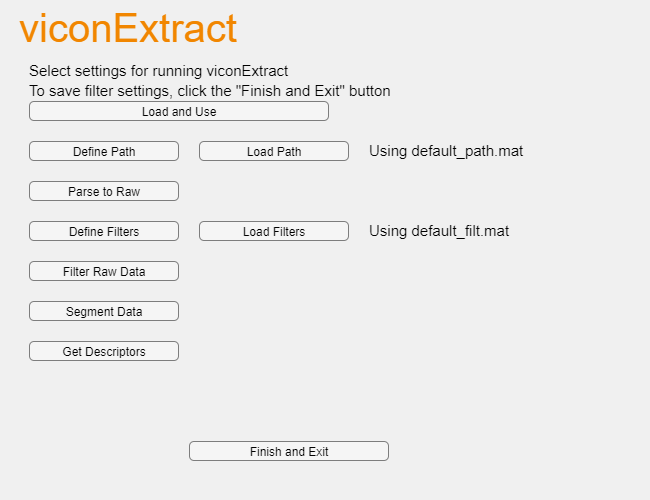

addpath(genpath(pwd));  % PWD maximum depth is ...\viconExtract to run

vesettings = importsettings();

ve_gui = viconExtract_gui();

Runtime settings

function vesettings = importsettings()
    vesettings = struct('dontuse', 'dontuse');

    vesettings.import_override = false;     % default is false

    % false forces using filtered forceplate_force_z for segmentation
    % forcing filtered forceplate z may cause unintended/faulty behavior from GRFSegment
    vesettings.forceplatez_override = true;    % default is true
    
    vesettings = rmfield(vesettings, 'dontuse');
end